# Standard Radio - GSM

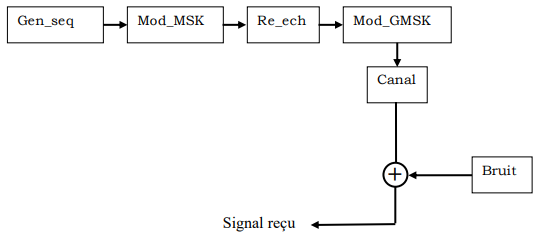

## Objectif du TP : 

Ecrire un script principal qui permettra de lancer toute la chaîne d’émission modélisée en bande de base ci-après, tout en représentant sur des figures le filtre Gaussien qui sera donné au cours de la séance sous format de fichier .mat , la constellation du signal généré après les modulations MSK et GMSK et en fin le signal après ajout du bruit et de l’effet du canal.

## I) Création du module GEN_SEQ

Le module GEN_SEQ permet de générer une séquence binaire aléatoire de longueur l.

%Définition de la fonction GEN_SEQ qui permet de créer ce module
l=300;
GEN_SEQ=randi([0,1],1,l); %Génère une séquence binaire aléatoire de 0 et de 1
disp(GEN_SEQ);

  Columns 1 through 29

     1     1     0     0     0     1     0     1     1     0     1     0     1     0     1     0     1     1     1     0     1     1     0     1     1     0     1     0     0

  Columns 30 through 58

     1     1     1     1     0     0     1     1     1     0     0     1     0     0     1     0     1     1     1     1     0     1     1     1     1     1     0     1     0

  Columns 59 through 87

     1     1     1     0     1     1     1     0     0     0     1     1     1     1     1     1     1     1     1     0     1     0     1     0     0     1     1     1     1

  Columns 88 through 116

     0     1     1     1     0     0     1     1     0     1     0     1     1     1     0     0     1     0     0     0     1     0     0     0     0     0     0     0     0

  Columns 117 through 145

     1     1     0     1     1     1     0     1     1     0     0     0     1     0     1     1     1     0     0     1     1     1     0     0     0     1     0     1 

## II) Création du module MOD_MSK

Le module MOD_MSK permet la modulation MSK d’une séquence binaire donnée.

Codage NRZ de la séquence binaire aléatoire générée

%Codage NRZ

%1ère méthode
% GEN_SEQ_NRZ=[];
% for i=1:length(GEN_SEQ)
%     if GEN_SEQ(i)==0
%         GEN_SEQ_NRZ=[GEN_SEQ_NRZ -1];
%     else if GEN_SEQ(i)==1
%         GEN_SEQ_NRZ=[GEN_SEQ_NRZ 1];
%     end
%     end
% end

%2nde méthode
GEN_SEQ_NRZ=(GEN_SEQ.*2-1)

GEN_SEQ_NRZ =      1     1    -1    -1    -1     1    -1     1     1    -1     1    -1     1    -1     1    -1     1     1     1    -1     1     1    -1     1     1    -1     1    -1    -1     1     1     1     1    -1    -1     1     1     1    -1    -1     1    -1    -1     1    -1     1     1     1     1    -1


Modulation MSK de ce signal codé en NRZ

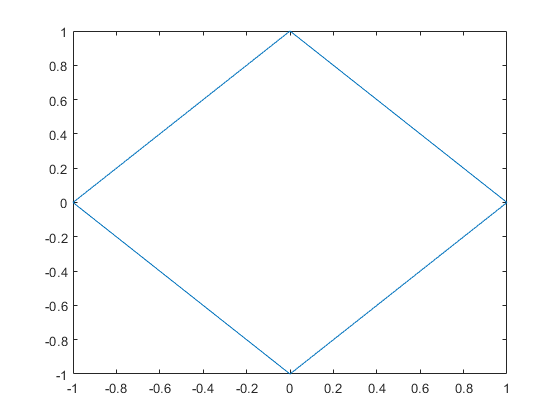

%Modulation MSK
MSK_MOD=zeros(1,l);
for i=1:l
    MSK_MOD(i)=GEN_SEQ_NRZ(i)*exp(1j*i*pi/2);
end

MSK_MOD;
plot(MSK_MOD);

## III) Création du module RE_ECH

Le module RE_ECH permet de sur-échantillonner un signal donné n fois sa fréquence. (Utilisation de la fonction resample).

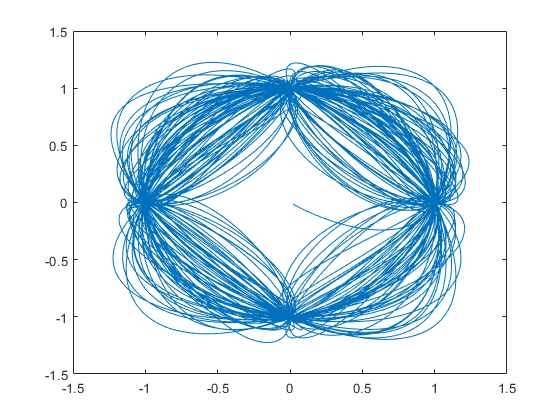

P=37;
Q=1;
RE_ECH=resample(MSK_MOD,P,Q);

plot(RE_ECH);

## IV) Création du module MOD_GMSK

Le module MOD_GMSK permet la modulation GMSK d’un signal.

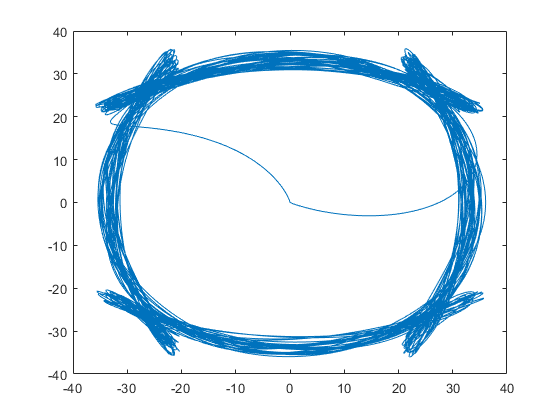

load g
MOD_GMSK=conv(RE_ECH,g);

plot(MOD_GMSK);

## V) Création du module NOISE

Le module NOISE permet de générer un bruit AWGN à partir du rapport signal à bruit (SNR) et de la fonction écart type (std) du signal.

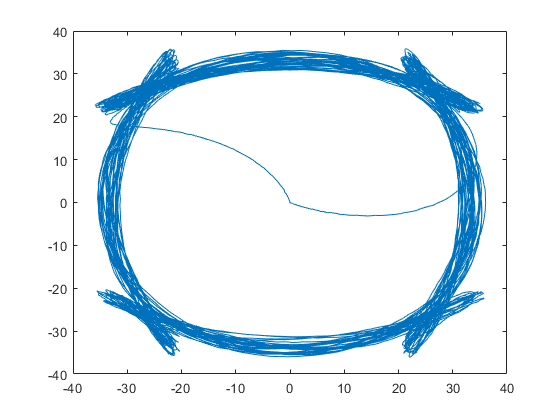

SNR=25;
NOISE=awgn(MOD_GMSK,SNR);

plot(NOISE);

## VI) Création du module CANAL

Le module CANAL permet l’ajout de l’effet d’un canal multi trajets, sachant que ce dernier joue un effet de filtre dont les coefficients en dB sont les suivants pour un canal RAx : co_canal=[0 -4 -8 -12 -16 -20] .

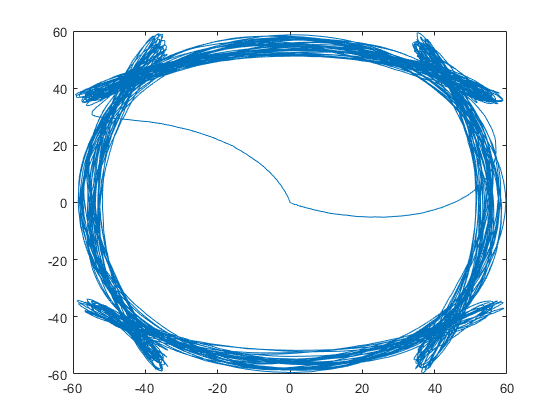

co_canal=[0 -4 -8 -12 -16 -20]; %Valeurs en dB
tv=size(co_canal); %Taille du vecteur co_canal
for i=1:tv(2)
    co_canal(i)=10^(co_canal(i)*0.1); %Les valeurs de co_canal se convertissent en linéaire
end
SNR=25;
CANAL=awgn(conv(MOD_GMSK,co_canal),SNR);
plot(CANAL);